# Process the intensity data from Idler

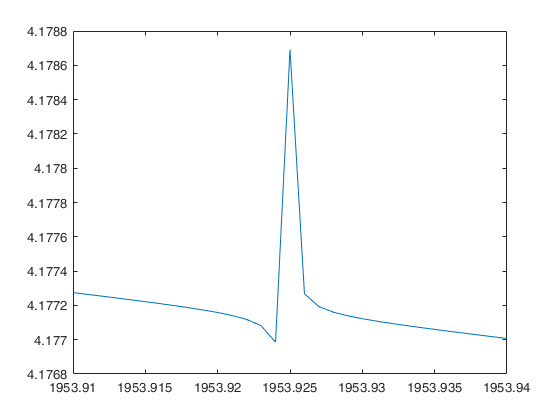

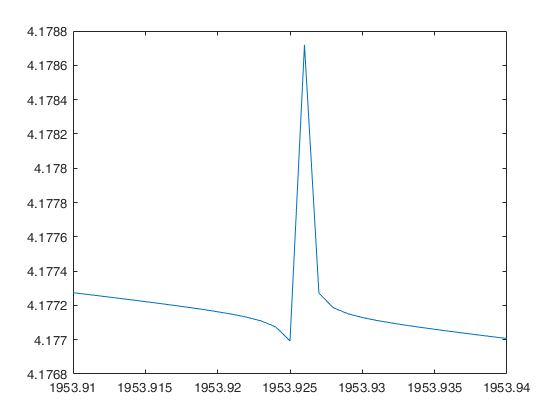

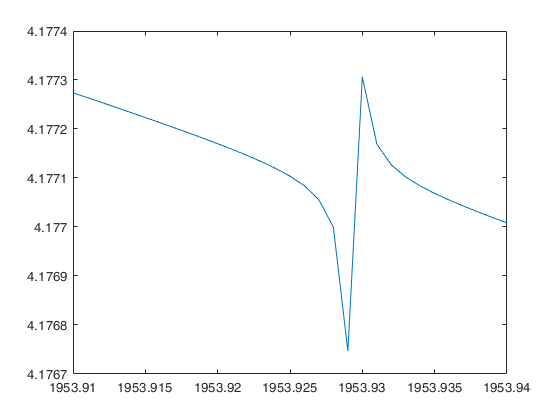

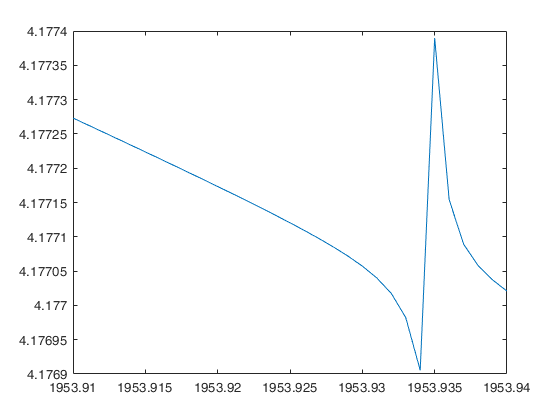

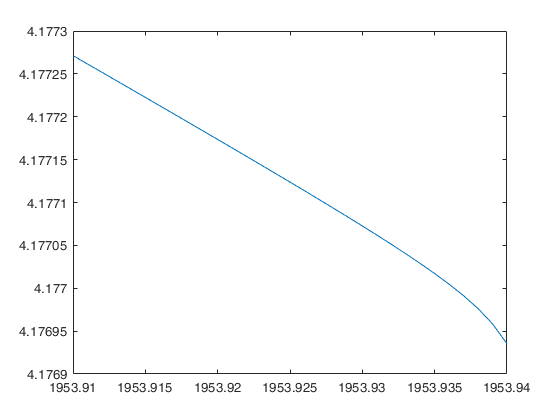

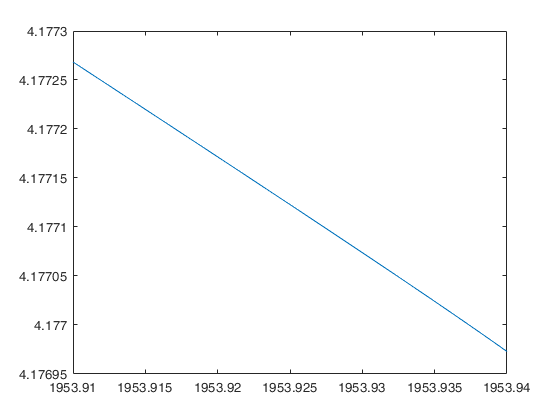

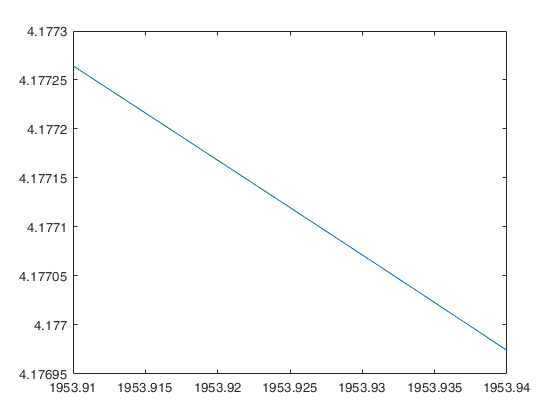

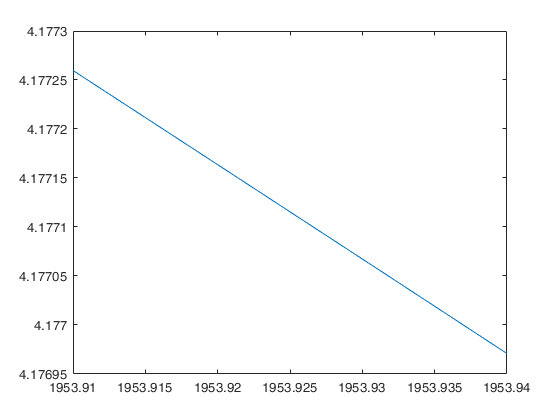

clear;
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\analysis');
eval("cylinder_dimer_no_substrate_110_2_4");
load([options.output_dir_final 'sweep_data.mat']);

scat_eff = [];

for theta = get_range("step", 0,0.1,1,"[deg]")
%    for phi = ["0[deg]" "90[deg]"]
%        for orientation_xy = "0[deg]"% "45[deg]" "90[deg]"]
%            data = sweep_data(sweep_data.theta == theta & sweep_data.phi == phi...
%                & sweep_data.orientation_xy == orientation_xy,:);
            data = sweep_data(sweep_data.theta == theta,:);
            
            derived_values = data.DerivedValues{1};
            scat_eff = [scat_eff; derived_values.signal.scat_eff'];
            
            wlengths = 299792458./derived_values.signal.freq;
            figure;
            plot(wlengths,derived_values.signal.scat_eff);
%        end
%    end
end

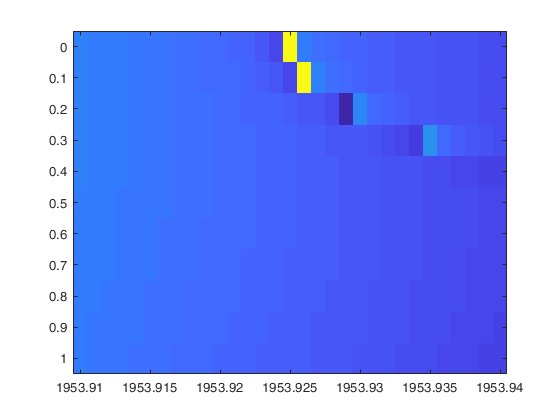

figure;
imagesc(wlengths, 0:0.1:1, scat_eff);